# 1D optimisation of droplet center

#### To generate optimisation procedure for the *(center of the)* initial droplet location

- Select variables for droplet and chose Target Shape

- Plot initial droplet shape based on chosen `x0`

- Use optimisation prosidure to find bes possition of droplet

**Looping erro**

- Set grid size to small value:` xMax = 10`

- If  |`x - x0`|` ~= x0`,   where   `x ≠ x0`

- Then `x_sol = x0 ~≠ x`

**Solution**

- make` xMax >> |x - x0|`

**Gradient distribution erro**

- If `|x - x0| `is too large,` TolX `is met 

- but` |x - x0| `is not close to zero

**Solution**

- Modifi ` costEvaluation...`

- Possibly to account for central difference

**or**

- Just have` x0 `sufficiently close to` x`

- `x0 `should be within targetshape rejion

clear; clc;

## **1) **

**Set some values**

y0 = .1084434390; % Raise droplet profile...
N = 100; % # sample points
A = 21; % Magnitude/Amplitude of droplet
% c0(1) = 0.001;  
% c0(2) = 0.023;
c1 = 0.0010;  
c2 = 0.0196;

tfinal = 10^5; % final time >> 1
xMax = 20; 
dx = 2*xMax/(N-1); % Stepsize
X = -xMax:dx:xMax; % Linespace/Mesh
k = 1/(2*xMax/N); %omega
% Possition / Shift
x0 = 0;

**Target Shape **`h_target`

h_target = 0.1*ones(size(X));
h_target(2.5 - X.^2/12>0.1) = 2.5 - X(2.5 - X.^2/12>0.1).^2/12;

## **2) **

**Solutions**

[tSpan,D1,D2,X,H0,myObjective_Possition,conds_Sol,...
    fval,exitflag,output,history,History,h_Sol,H_Sol]...
    = Disjoining(tfinal,dx,X,k,y0,N,A,c1,c2,h_target);

 
 Iteration   Func-count     min f(x)         Procedure
     0            1          41.8174         
     1            3          35.6472         initial simplex
     2            5          18.7048         expand
     3            7          5.82546         expand
     4            8          5.82546         reflect
     5           10          5.82546         contract inside
     6           12          5.26181         contract inside
     7           14          5.26181         contract inside
     8           16          5.08468         reflect
     9           18          4.01085         contract inside
    10           20          3.81538         reflect
    11           22          3.81538         contract inside
    12           24          3.81538         contract inside
    13           25          3.81538         reflect
    14           27          3.58152         expand
    15           29          3.23097         expand
    16           31          3.06858         refle

**Figures**

figure;

var = [A;N;k;y0]; 
% Set time span
tSpan = [1e-6 tfinal]; 
% Creating test matrix to soolve ODE
D1 = full(gallery('tridiag',N,-1,0,1));
D1(N,1)=1;D1(1,N)=-1;
D1 = D1/(2*dx);
D1 = sparse(D1); % D1
D2 = full(gallery('tridiag',N,1,-2,1));
D2(N,1)=1;D2(1,N)=1;
D2 = D2/dx^2;
D2 = sparse(D2); % D2
    
h1 = hFinal(history(2,:),X,var,D1,D2,tSpan);
H1 = deval(h1,tfinal);   

h2 = hFinal(history(3,:),X,var,D1,D2,tSpan);
H2 = deval(h2,tfinal); 

h3 = hFinal(history(4,:),X,var,D1,D2,tSpan);
H3 = deval(h3,tfinal);   

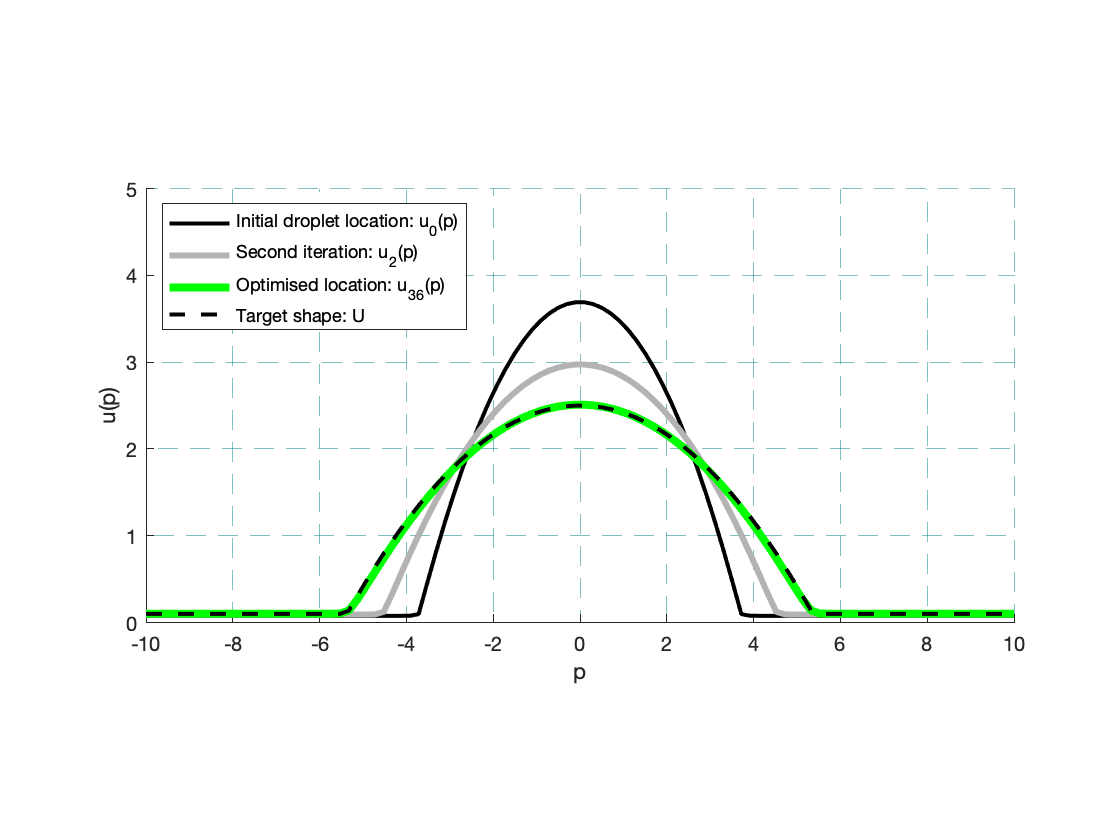

figure;
hold on
pbaspect([2 1 1]);
plot(X,H0,'k-','linewidth',2);
%pp1 = plot(X,H1,':','Color',[0.5 0.5 0.5],'linewidth',3);
pp2 = plot(X,H2,'-','Color',[0.7 0.7 0.7],'linewidth',3);
plot(X,H_Sol,'g-','linewidth',4);
plot(X,h_target,'k--','linewidth',2);

legend('Initial droplet location: u_0(p)','Second iteration: u_{2}(p)','Optimised location: u_{36}(p)','Target shape: U','Location','northwest');
% title('2-D profile of droplet')
xlabel('p')
ylabel('u(p)')
xlim([-10 10]);
ylim([0 5]);
grid on

ax = gca;
ax.GridColor = [0 .5 .5];
ax.GridLineStyle = '--';
ax.GridAlpha = 0.5;

hold off

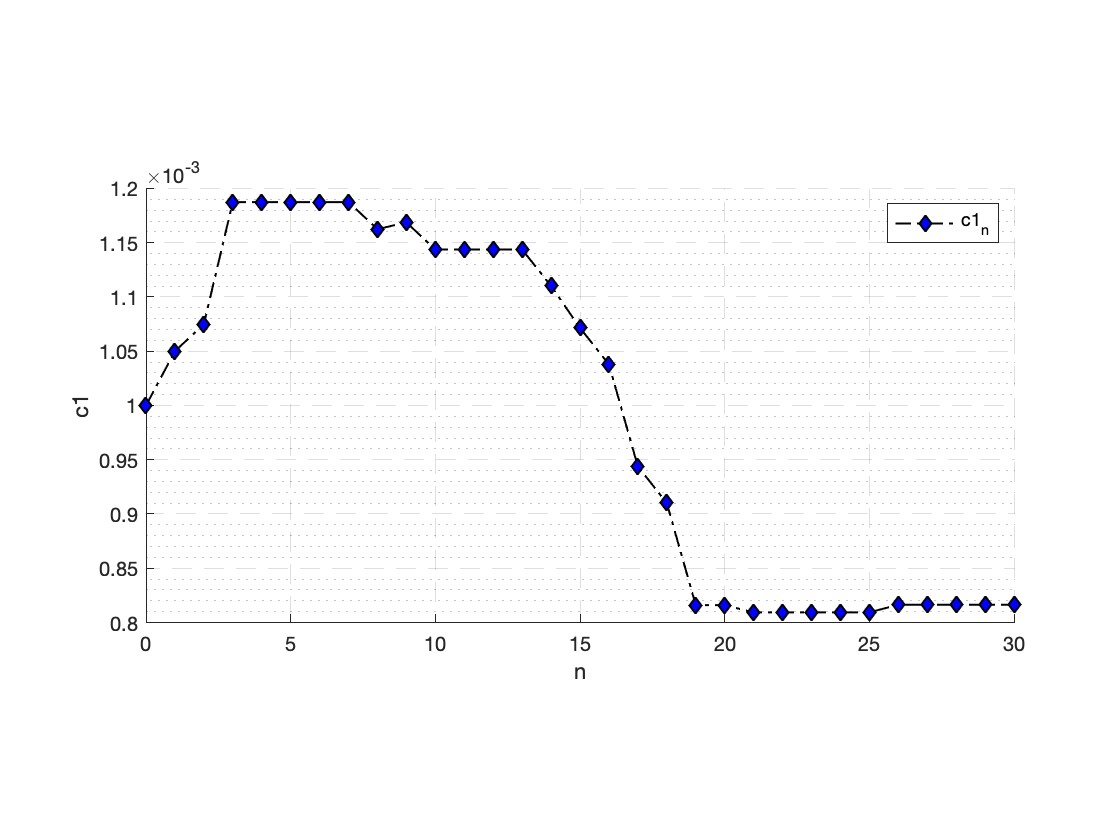

n = size(history);
n = n(1);

C1 = history(:,1);
C2 = history(:,2);

B1 = C1;
B2 = C2;

B1i = B1/B1(1);
B2i = B2/B2(1);

B = sqrt((B1/max(B1)).^2 + (B2/max(B2)).^2);

dataH = abs(history(:,:))';
dataHi = abs(history(:,:))';
lineH = 0:1:n-1;
lineHi = 0:1:n-1;

xi = linspace(1, n, 100); 

yi1 = interp1(lineHi, B1, xi, 'spline', 'extrap');
yi2 = interp1(lineHi, B2, xi, 'spline', 'extrap');

zi1 = interp1(lineHi, B1i, xi, 'spline', 'extrap');
zi2 = interp1(lineHi, B2i, xi, 'spline', 'extrap');
zi = interp1(lineHi, B, xi, 'spline', 'extrap');


figure;
plot(lineHi,B1,'k-.diamond',...
    'MarkerSize',6,...
    'MarkerFaceColor','b',...
    'LineWidth',1);
pbaspect([2 1 1]);
box off

ylabel('c1');
xlabel('n');
legend('c1_n');

set(gca,'xtick',0:5:100);

xlim([0 30]);
%ylim([0 75]);

ax = gca;
ax.GridLineStyle = '--';
ax.XGrid = 'on';
ax.YGrid = 'on';
ax.MinorGridLineStyle =':';
ax.XMinorGrid = 'off';
ax.YMinorGrid = 'on';

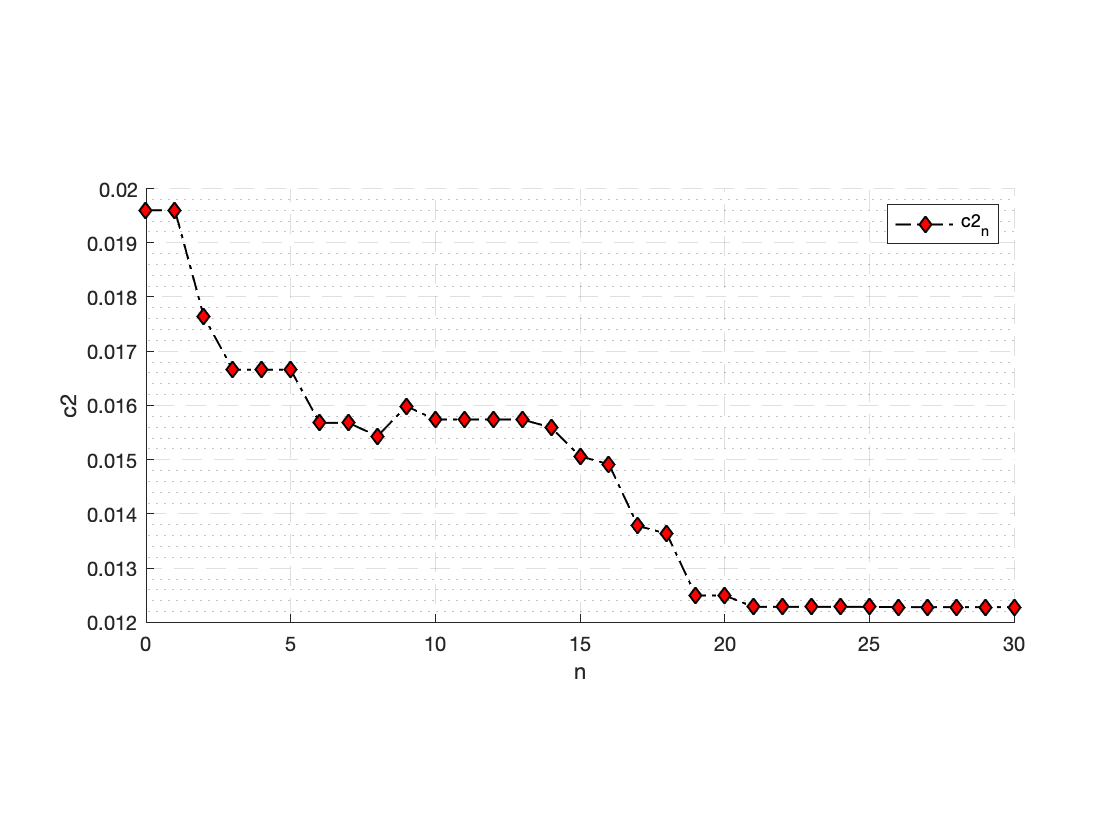


figure;
S2 = plot(lineHi,B2,'k-.diamond',...
    'MarkerSize',6,...
    'MarkerFaceColor','r',...
    'LineWidth',1);

pbaspect([2 1 1]);
box off

ylabel('c2');
xlabel('n');
legend('c2_n');

set(gca,'xtick',0:5:100);

xlim([0 30]);

ax = gca;
ax.GridLineStyle = '--';
ax.XGrid = 'on';
ax.YGrid = 'on';
ax.MinorGridLineStyle =':';
ax.XMinorGrid = 'off';
ax.YMinorGrid = 'on';

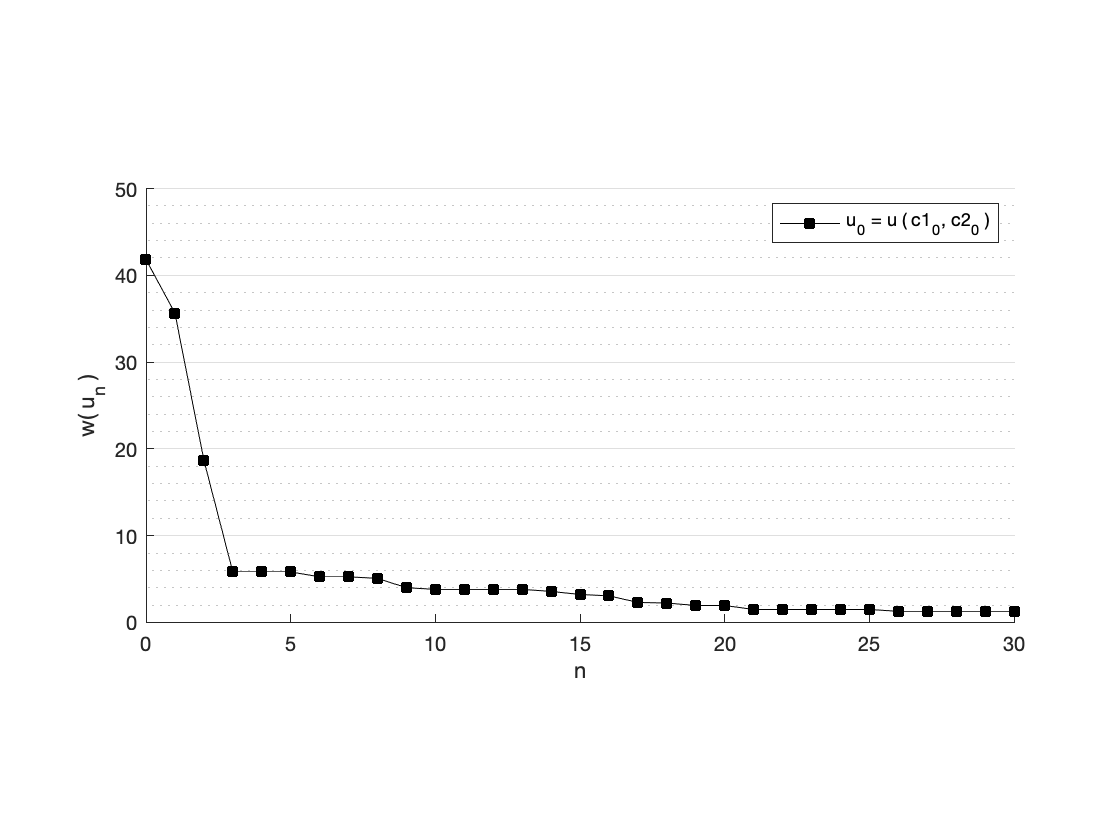

HHH = History - History(end);

figure;
plot(lineHi,History,'k-s',...
    'MarkerSize',6,...
    'MarkerFaceColor','k');
pbaspect([2 1 1]);
box off

% title('Iterative evolution of droplet distance to optimal location');
ylabel('w( u_n )');
xlabel('n');
legend('u_0 = u ( c1_0, c2_0 )');

set(gca,'xtick',0:5:100);
set(gca,'ytick',0:10:500);

xlim([0 30]);
ylim([0 50]);

ax = gca;
ax.GridLineStyle = '-';
ax.XGrid = 'off';
ax.YGrid = 'on';
ax.MinorGridLineStyle =':';
ax.XMinorGrid = 'off';
ax.YMinorGrid = 'on';

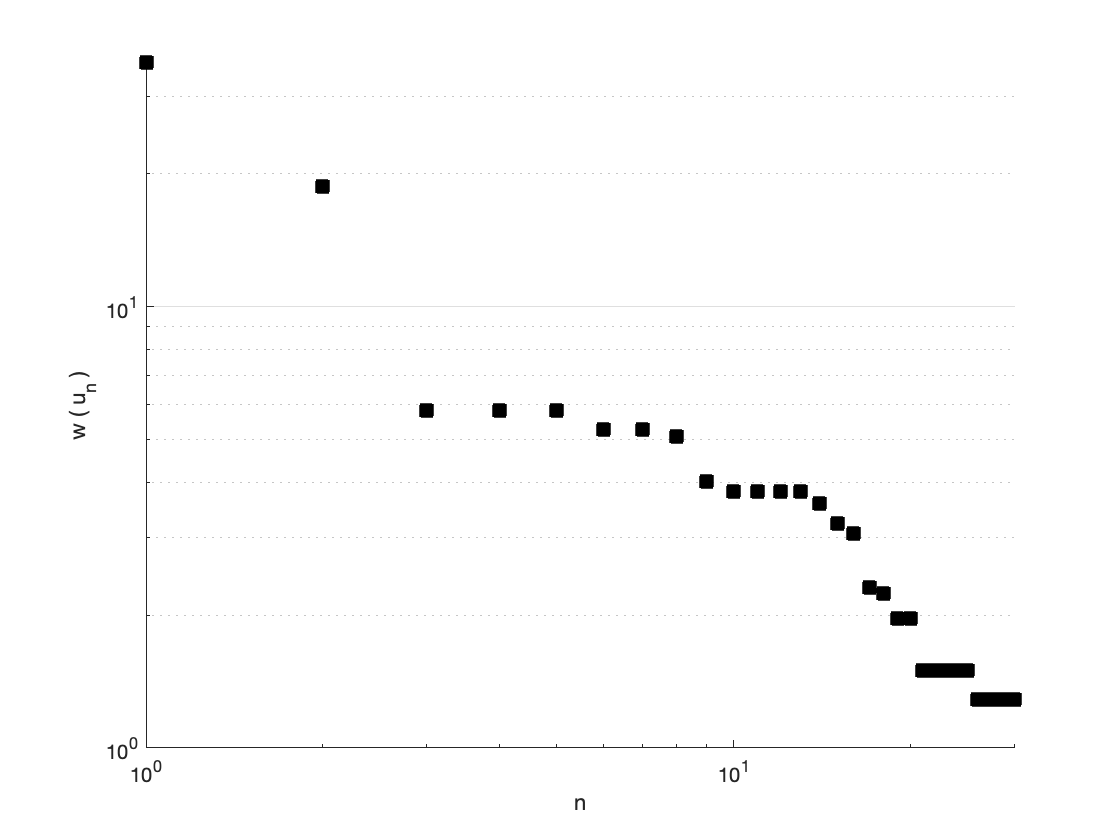

figure;
loglog(lineHi,History,'ks',...
    'MarkerSize',8,...
    'MarkerFaceColor','k',...
    'LineWidth',1);
box off

% title('Iterative evolution of droplet distance to optimal location');
ylabel('w ( u_n )');
xlabel('n');

ax = gca;
ax.GridLineStyle = '-';
ax.XGrid = 'off';
ax.YGrid = 'on';
ax.MinorGridLineStyle =':';
ax.XMinorGrid = 'off';
ax.YMinorGrid = 'on';

we see a faily straight line for the first 6 iterations  with a logspace x (iterations) axis